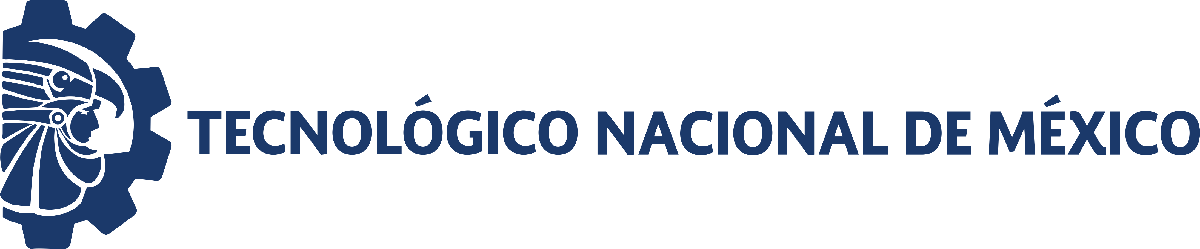                                 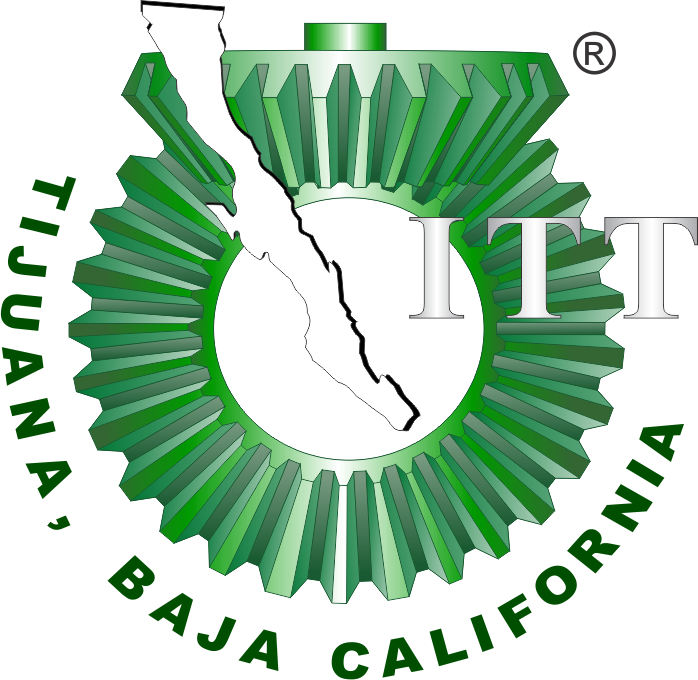

# Práctica 2: Sitema respiratorio

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

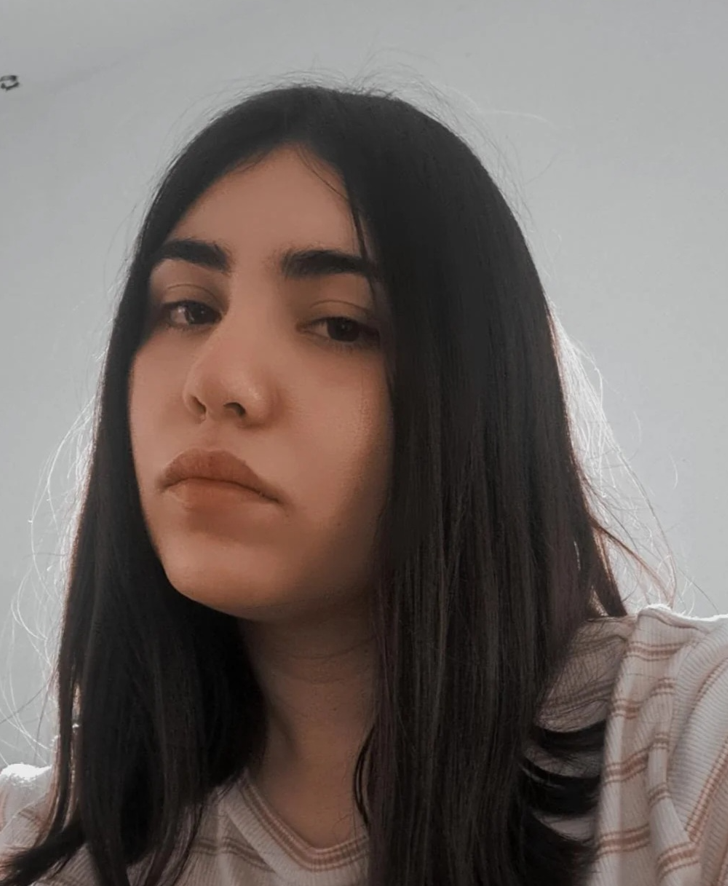

Nombre del alumno: **Damian Arroyo Perla Guadalupe**

Número de control: **21212150**

Correo institucional: **l21212150@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '30';
file = 'sysp3';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';

## Rendimiento del controlador

kP = 171.24.58

kI = 4040.7036

kD = 0.92706

Settling time = 0.0957 s

Overshoot = 9.62%

Peak = 1.1

## Respiración normal

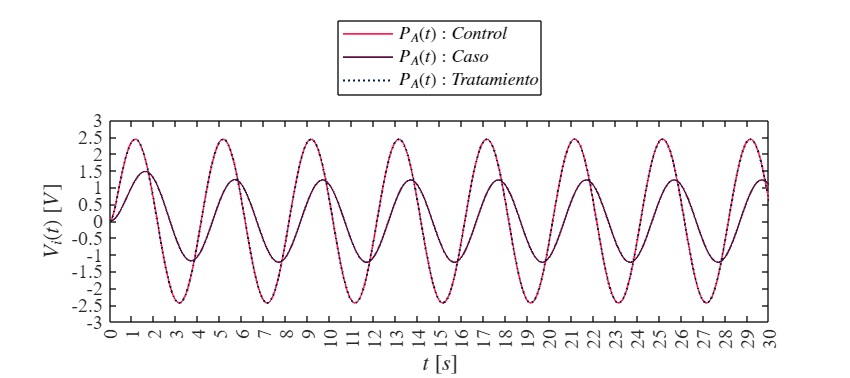

set_param('sysp3/Pao(t)','sw','1');
set_param('sysp3/PID Controller','P', '1326.1375');
set_param('sysp3/PID Controller','I', '70371.2725 ');
set_param('sysp3/PID Controller','D', '6.1879');
Signal = 'Respiración normal';
N = sim(file, parameters);
plotsignal(N.t, N.PAx, N.PAy, N.PAz, Signal)

## Respiración Anormal

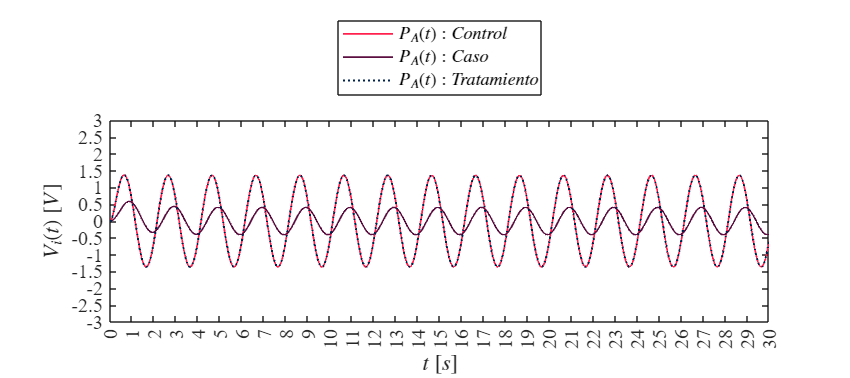

set_param('sysp3/Pao(t)','sw','0');
set_param('sysp3/PID Controller','P', '1326.1375');
set_param('sysp3/PID Controller','I', '70371.2725 ');
set_param('sysp3/PID Controller','D', '6.1879');
Signal = 'Respiración Anormal';
N = sim(file, parameters);
plotsignal(N.t, N.PAx, N.PAy, N.PAz, Signal)

## Función

function plotsignal(t, PAx, PAy, PAz, Signal)
    set(figure(), 'Color', 'w')
    set(gcf, 'Units', 'Centimeters', 'Position',[1,1,18,8])
    set(gca, 'FontName', 'Times New Roman')
    fontsize(12, 'points')
    rosa = [255/255, 32/255, 78/255];
    morado = [93/255, 14/255, 65/255];
    azul = [0/255, 34/255, 77/255];
    hold on; grid off; box on

    t = t(:); 
    
    % Convertir objetos timeseries a arreglos numéricos
    if isa(PAx, 'timeseries'), PAx = PAx.Data(:); end
    if isa(PAy, 'timeseries'), PAy = PAy.Data(:); end
    if isa(PAz, 'timeseries'), PAz = PAz.Data(:); end


    plot(t, PAx, 'LineWidth', 1,'Color',rosa)
    plot(t, PAy, 'LineWidth', 1,'Color', morado)
    plot(t, PAz,':', 'LineWidth', 1.2,'Color', azul)
    
    xlabel('$t$ $[s]$',  'Interpreter','Latex')
    ylabel('$V_i (t)$ $[V]$',  'Interpreter','Latex')

   L = legend('$P_A(t): Control$', '$P_A(t): Caso$', '$P_A(t): Tratamiento$');
    set(L, 'Interpreter', 'latex', 'Location', 'northoutside', 'Box', 'on')
    
    if Signal == "Respiración normal"
        xlim([0, 30]); xticks(0:1:30)
        ylim([-3, 3]); yticks(-3:0.5:3)
    elseif Signal == "Respiración Anormal"
        xlim([0, 30]); xticks(0:1:30)
        ylim([-3, 3]); yticks(-3:0.5:3)
    end

   exportgraphics(gcf,[Signal,'.pdf'], 'ContentType', 'Vector')
   exportgraphics(gcf,[Signal,'.png'], 'Resolution', 600);
   print(Signal, '-dsvg');
   print(Signal, '-depsc');
    
end